# Examen Localización de un robot diferencial

Ana Itzel Hernández García 

Limpieza de pantalla

clear all
close all
clc

**Pregunta 3**

Considerando los parámetros del robot descrito en el reactivo 2. Obtén la tabla de las

señales de entrada ω_R (rad/s) y ω_L (rad/s) requeridas en cada instante de muestreo si

se desea obtener una trayectoria circular con un radio de 20m, cuyo centro sea el origen

(0, 0). Genera la simulación en Matlab.

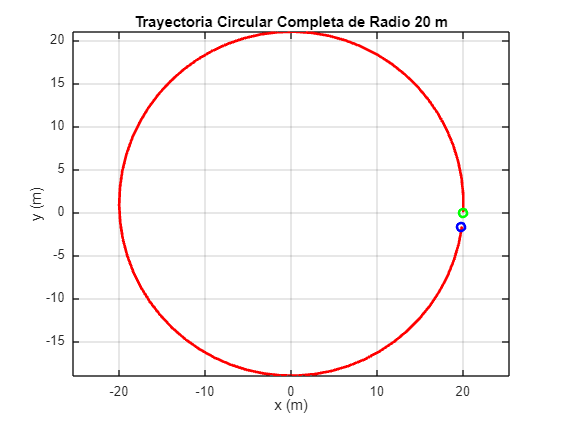


%%% PARÁMETROS DEL ROBOT %%%
r = 0.1;     % Radio de las ruedas (m)
L = 0.4;     % Distancia entre ruedas (m)
R = 20;      % Radio deseado de la trayectoria (m)
v = 1;       % Velocidad lineal (m/s)
w_robot = v / R;   % Velocidad angular necesaria (rad/s)

% Calcular el tiempo necesario para dar una vuelta completa
T = 2*pi / w_robot;

%%% TIEMPO DE SIMULACIÓN %%%
ts = 2;
t = 0:ts:T;
N = length(t);

%%% INICIALIZACIÓN DE VARIABLES %%%
x1 = zeros(1,N);
y1 = zeros(1,N);
phi = zeros(1,N);

x1(1) = R;       % Comienza en (20, 0)
y1(1) = 0;
phi(1) = pi/2;   % Apuntando hacia arriba para que circule antihorario

%%% VELOCIDADES CONSTANTES %%%
u = v * ones(1,N);
w = w_robot * ones(1,N);

%%% SIMULACIÓN DE LA TRAYECTORIA CIRCULAR %%%
for k = 1:N-1
    phi(k+1) = phi(k) + w(k)*ts;
    x1(k+1) = x1(k) + u(k)*cos(phi(k))*ts;
    y1(k+1) = y1(k) + u(k)*sin(phi(k))*ts;
end

%%% GRAFICADO 2D DE TRAYECTORIA %%%
figure
plot(x1, y1, 'r', 'LineWidth', 2)
hold on
plot(x1(1), y1(1), 'go', 'LineWidth', 2) % Inicio
plot(x1(end), y1(end), 'bo', 'LineWidth', 2) % Fin
axis equal
grid on
xlabel('x (m)')
ylabel('y (m)')
title('Trayectoria Circular Completa de Radio 20 m')


%%% CÁLCULO DE VELOCIDADES DE RUEDAS %%%
w_r = (2*v + w_robot*L)/(2*r);
w_l = (2*v - w_robot*L)/(2*r);
fprintf('w_R = %.3f rad/s\nw_L = %.3f rad/s\n', w_r, w_l);

w_R = 10.100 rad/s
w_L = 9.900 rad/s


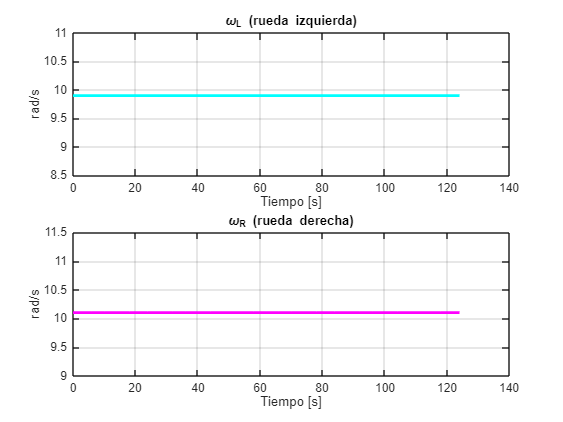


%%% GRAFICAR VELOCIDADES DE RUEDAS %%%
figure
subplot(2,1,1)
plot(t, w_l*ones(1,N), 'c','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('rad/s'), title('\omega_L (rueda izquierda)')

subplot(2,1,2)
plot(t, w_r*ones(1,N), 'm','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('rad/s'), title('\omega_R (rueda derecha)')

    %% TABLA DE VELOCIDADES (opcional para insertar en Word) %%%
tabla = table(t', repmat(w_r, N, 1), repmat(w_l, N, 1), ...
    'VariableNames', {'Tiempo_s', 'w_R_rad_s', 'w_L_rad_s'});
disp(tabla)

    Tiempo_s    w_R_rad_s    w_L_rad_s
    ________    _________    _________

        0         10.1          9.9   
        2         10.1          9.9   
        4         10.1          9.9   
        6         10.1          9.9   
        8         10.1          9.9   
       10         10.1          9.9   
       12         10.1          9.9   
       14         10.1          9.9   
       16         10.1          9.9   
       18         10.1          9.9   
       20         10.1          9.9   
       22         10.1          9.9   
       24         10.1          9.9   
       26         10.1          9.9   
       28         10.1          9.9   
       30         10.1          9.9   
       32         10.1          9.9   
       34         10.1          9.9   
       36         10.1          9.9   
       38         10.1          9.9   
       40         10.1          9.9   
